# Example 1.8

% Jonghwan Lee, Jan 2021

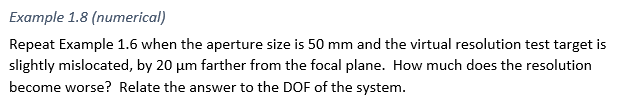

## Prepare variables.

All lengths are in [um].

clear;
nx = 100;  ny = 80;  % number of sampling points (pixels of the camera)
dxImg = 10;  % the sensor pixel size [um]
zImg = 300e3;  % the lens-sensor distance [um]
f = 100e3;  % the focal length [um]
diaAper = 50e3;  % the aperture diameter [um]

Load the virtual target.

load("virtualTarget.mat","phySamp");  % phySamp : the virtual resolution test target
phySamp = double(phySamp);  % convert the boolean array to a double array for further computation
[nxp,nyp] = size(phySamp)  % size of the physical sample [pixels]

nxp = 10000

nyp = 8000

dxp = 0.1;  % um per pixel of the physical sample
disp(['Sample size (um) = ' mat2str([nxp nyp]*dxp)])

Sample size (um) = [1000 800]


## Determine the sampling intervals and kernel sizes.

Determine the sampling interval on the focal plane (not used but as a reference).

zFP = 1/(1/f-1/zImg)  % the focal plane position [um] (Eq. 1.7)

zFP = 1.5000e+05

dxFP = zFP/zImg*dxImg  % the sampling interval on the focal plane [um] (Eq. 1.8)

dxFP = 5.0000

Determine the sampling interval and the kernel size on the sample plane.

zSamp = zFP + 20;  % the sample position [um]
dxSamp = zSamp/zImg*dxImg  % the sampling interval on the sample plane [um] (Eq. 1.4)

dxSamp = 5.0007

dxKern = zSamp/zImg*dxImg + diaAper*abs(zSamp/zFP-1)  % kernel size [um]

dxKern = 11.6673

## Use convn().

Make a 2D array for the kernel.

dxKernPhy = round(dxKern/dxp);  % the kernel size in terms of physical pixel number
kern = ones(dxKernPhy,dxKernPhy);
kern = kern/sum(kern(:));  % normalize the kernel when using convn()

Perform convolution of `phySamp` with the kernel.  This process can require large memory and take a long time depending on the kernel size.

tic
phySampConv = convn(phySamp,kern,'same');  
toc

Elapsed time is 10.447342 seconds.


Pick the data from the center of each "pixel" on the sample plane.

dxSamPhy = round(dxSamp/dxp);  % the sampling interval in terms of the physical pixel number
img = phySampConv(round(dxSamPhy/2):dxSamPhy:end,round(dxSamPhy/2):dxSamPhy:end);

Crop the resulting image if it is larger than the FOV.

if size(img,1) > nx
    img = img(1:nx,:);
end
if size(img,2) > ny
    img = img(:,1:ny);
end

Show the resulting image.

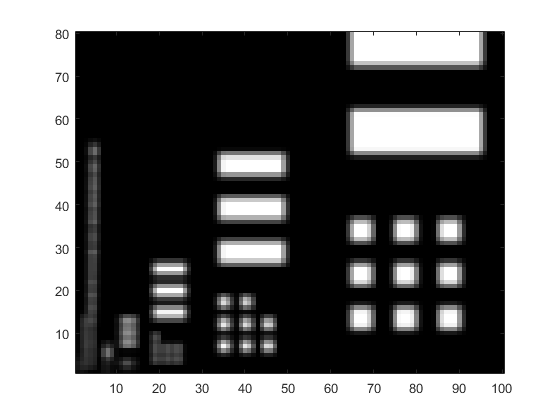

figure;  colormap(gray);
imagesc(img');
set(gca,'ydir','normal');
axis image;

## Determine the resolution.

When visually inspecting, the lines of the 7-dots column is clear (2^7=128 pixels or 12.8-um).  Thus, the resolution is better than 12.8 um.  But, whether the 6-dots column (6.4 um) pattern would pass the Rayleigh criterion is unclear.

We can extract the intensity profiles like we did in Example 1.6. 

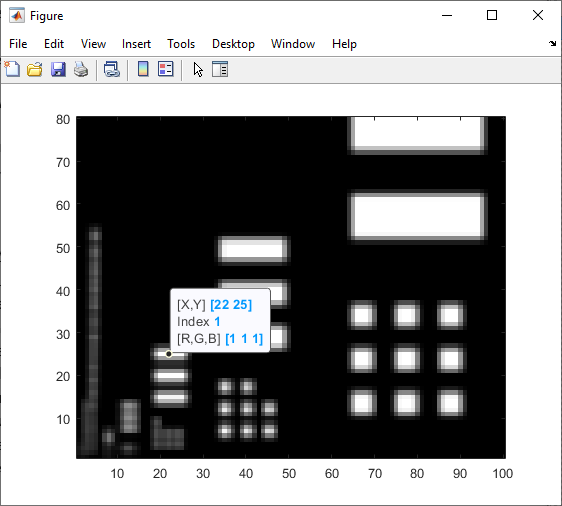

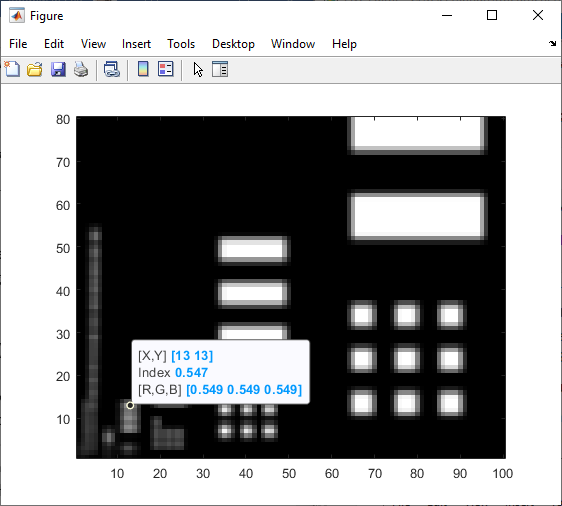

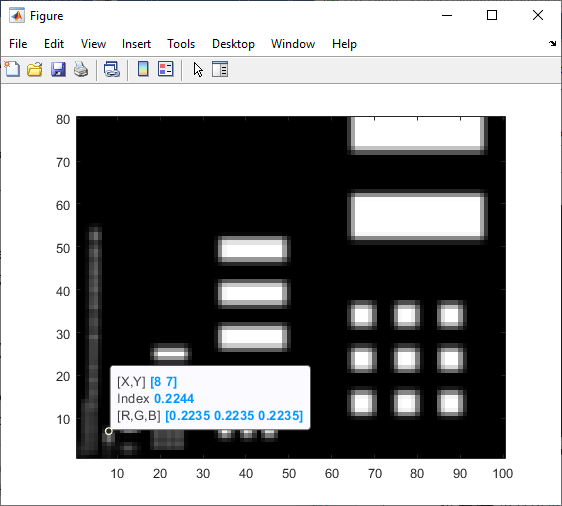

ix128 = 22;  % the center X position of the 12.8-um pattern
ix64 = 13;  % the center X position of the 6.4-um pattern

Extract and show the intensity profiles.

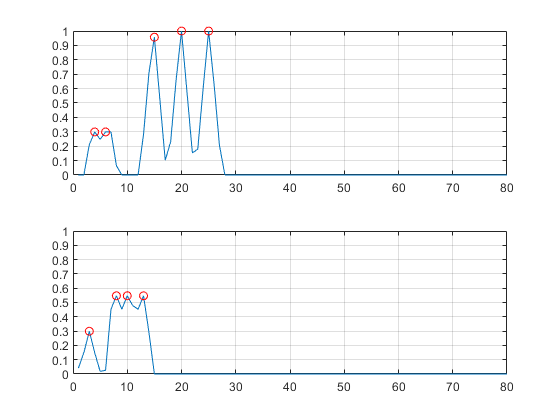

figure;
subplot(211);  
    I = img(ix128,:);
    plot(I);
    [pks,locs] = findpeaks(I);
    line(locs,pks,'linestyle','none','marker','o','color','r');
    ylim([0 1]);  set(gca,'ytick',(0:.1:1));  grid on;
subplot(212);
    I = img(ix64,:);
    plot(I);
    [pks,locs] = findpeaks(I);
    line(locs,pks,'linestyle','none','marker','o','color','r');
    ylim([0 1]);  set(gca,'ytick',(0:.1:1));  grid on;

- We can see 3 peaks in the 6.4-um pattern, but they do not pass the criterion (25% dip minimum).